# Machine Learning Online Class

## Initialization

clear ; close all; clc

## ================== Part 1: Load Example Dataset ===================

fprintf('Visualizing example dataset for PCA.\n\n');

Visualizing example dataset for PCA.



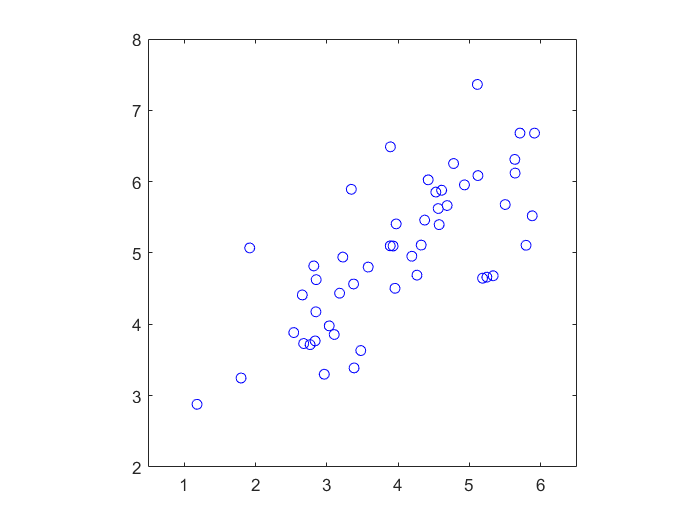


%  The following command loads the dataset. You should now have the 
%  variable X in your environment
load ('ex7data1.mat');

%  Visualize the example dataset
plot(X(:, 1), X(:, 2), 'bo');
axis([0.5 6.5 2 8]); axis square;


fprintf('Program paused. Press enter to continue.\n');

Program paused. Press enter to continue.


pause;

## =============== Part 2: Principal Component Analysis ===============

fprintf('\nRunning PCA on example dataset.\n\n');


Running PCA on example dataset.



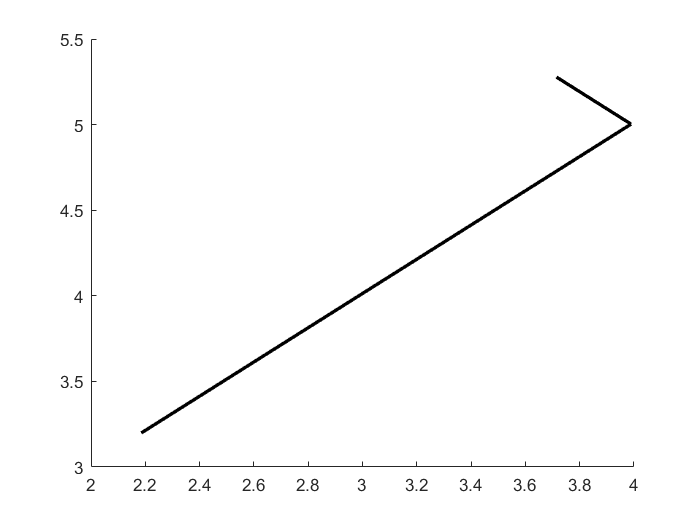


%  Before running PCA, it is important to first normalize X
[X_norm, mu, sigma] = featureNormalize(X);

%  Run PCA
[U, S] = pca(X_norm);

%  Compute mu, the mean of the each feature

%  Draw the eigenvectors centered at mean of data. These lines show the
%  directions of maximum variations in the dataset.
hold on;
drawLine(mu, mu + 1.5 * S(1,1) * U(:,1)', '-k', 'LineWidth', 2);
drawLine(mu, mu + 1.5 * S(2,2) * U(:,2)', '-k', 'LineWidth', 2);
hold off;


fprintf('Top eigenvector: \n');

Top eigenvector: 


fprintf(' U(:,1) = %f %f \n', U(1,1), U(2,1));

 U(:,1) = -0.707107 -0.707107 


fprintf('\n(you should expect to see -0.707107 -0.707107)\n');


(you should expect to see -0.707107 -0.707107)



fprintf('Program paused. Press enter to continue.\n');

Program paused. Press enter to continue.


pause;

## =================== Part 3: Dimension Reduction ===================

fprintf('\nDimension reduction on example dataset.\n\n');


Dimension reduction on example dataset.




%  Plot the normalized dataset (returned from pca)
plot(X_norm(:, 1), X_norm(:, 2), 'bo');
axis([-4 3 -4 3]); axis square

%  Project the data onto K = 1 dimension
K = 1;
Z = projectData(X_norm, U, K);
fprintf('Projection of the first example: %f\n', Z(1));

Projection of the first example: 1.481274


fprintf('\n(this value should be about 1.481274)\n\n');


(this value should be about 1.481274)




X_rec  = recoverData(Z, U, K);
fprintf('Approximation of the first example: %f %f\n', X_rec(1, 1), X_rec(1, 2));

Approximation of the first example: -1.047419 -1.047419


fprintf('\n(this value should be about  -1.047419 -1.047419)\n\n');


(this value should be about  -1.047419 -1.047419)




%  Draw lines connecting the projected points to the original points
hold on;
plot(X_rec(:, 1), X_rec(:, 2), 'ro');
for i = 1:size(X_norm, 1)
    drawLine(X_norm(i,:), X_rec(i,:), '--k', 'LineWidth', 1);
end
hold off

fprintf('Program paused. Press enter to continue.\n');

Program paused. Press enter to continue.


pause;

## =============== Part 4: Loading and Visualizing Face Data =============

fprintf('\nLoading face dataset.\n\n');


Loading face dataset.



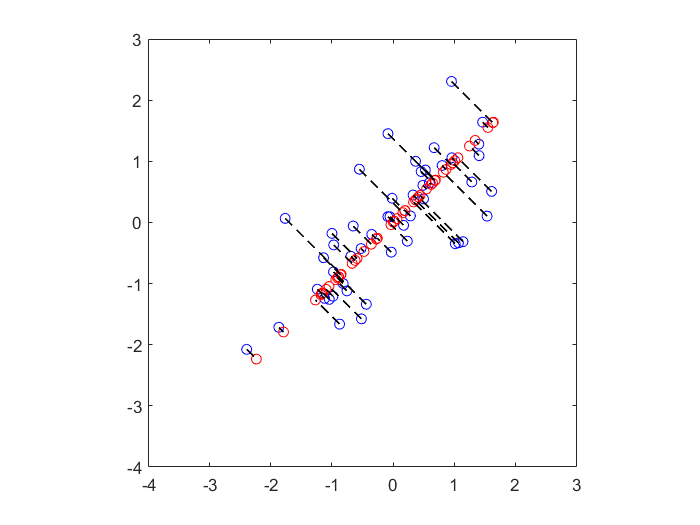


%  Load Face dataset
load ('ex7faces.mat')

%  Display the first 100 faces in the dataset
displayData(X(1:100, :));


fprintf('Program paused. Press enter to continue.\n');

Program paused. Press enter to continue.


pause;

## =========== Part 5: PCA on Face Data: Eigenfaces ===================

fprintf(['\nRunning PCA on face dataset.\n' ...
         '(this might take a minute or two ...)\n\n']);


Running PCA on face dataset.
(this might take a minute or two ...)



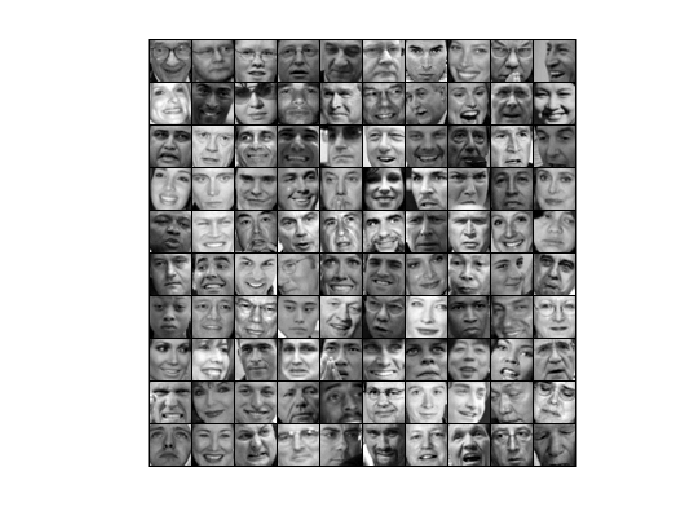


%  Before running PCA, it is important to first normalize X by subtracting 
%  the mean value from each feature
[X_norm, mu, sigma] = featureNormalize(X);

%  Run PCA
[U, S] = pca(X_norm);

%  Visualize the top 36 eigenvectors found
displayData(U(:, 1:36)');


fprintf('Program paused. Press enter to continue.\n');

Program paused. Press enter to continue.


pause;

## ============= Part 6: Dimension Reduction for Faces =================

fprintf('\nDimension reduction for face dataset.\n\n');


Dimension reduction for face dataset.




K = 100;
Z = projectData(X_norm, U, K);

fprintf('The projected data Z has a size of: ')

The projected data Z has a size of: 

fprintf('%d ', size(Z));

5000 100 


fprintf('\n\nProgram paused. Press enter to continue.\n');



Program paused. Press enter to continue.


pause;

## ==== Part 7: Visualization of Faces after PCA Dimension Reduction ====

fprintf('\nVisualizing the projected (reduced dimension) faces.\n\n');


Visualizing the projected (reduced dimension) faces.




K = 100;
X_rec  = recoverData(Z, U, K);

        1024        1024



Unable to perform assignment because the size of the left side is 1-by-1024 and the size of the right side is 1-by-100.

Error in recoverData (line 28)
        X_rec(i, :) = v' * U(j, K)';


% Display normalized data
subplot(1, 2, 1);
displayData(X_norm(1:100,:));
title('Original faces');
axis square;

% Display reconstructed data from only k eigenfaces
subplot(1, 2, 2);
displayData(X_rec(1:100,:));
title('Recovered faces');
axis square;

fprintf('Program paused. Press enter to continue.\n');
pause;

## === Part 8(a): Optional (ungraded) Exercise: PCA for Visualization ===

close all; close all; clc

% Reload the image from the previous exercise and run K-Means on it
% For this to work, you need to complete the K-Means assignment first
A = double(imread('bird_small.png'));

% If imread does not work for you, you can try instead
%   load ('bird_small.mat');

A = A / 255;
img_size = size(A);
X = reshape(A, img_size(1) * img_size(2), 3);
K = 16; 
max_iters = 10;
initial_centroids = kMeansInitCentroids(X, K);
[centroids, idx] = runkMeans(X, initial_centroids, max_iters);

%  Sample 1000 random indexes (since working with all the data is
%  too expensive. If you have a fast computer, you may increase this.
sel = floor(rand(1000, 1) * size(X, 1)) + 1;

%  Setup Color Palette
palette = hsv(K);
colors = palette(idx(sel), :);

%  Visualize the data and centroid memberships in 3D
figure;
scatter3(X(sel, 1), X(sel, 2), X(sel, 3), 10, colors);
title('Pixel dataset plotted in 3D. Color shows centroid memberships');
fprintf('Program paused. Press enter to continue.\n');
pause;

## === Part 8(b): Optional (ungraded) Exercise: PCA for Visualization ===

Use PCA to project this cloud to 2D for visualization

% Subtract the mean to use PCA
[X_norm, mu, sigma] = featureNormalize(X);

% PCA and project the data to 2D
[U, S] = pca(X_norm);
Z = projectData(X_norm, U, 2);

% Plot in 2D
figure;
plotDataPoints(Z(sel, :), idx(sel), K);
title('Pixel dataset plotted in 2D, using PCA for dimensionality reduction');
fprintf('Program paused. Press enter to continue.\n');
pause;